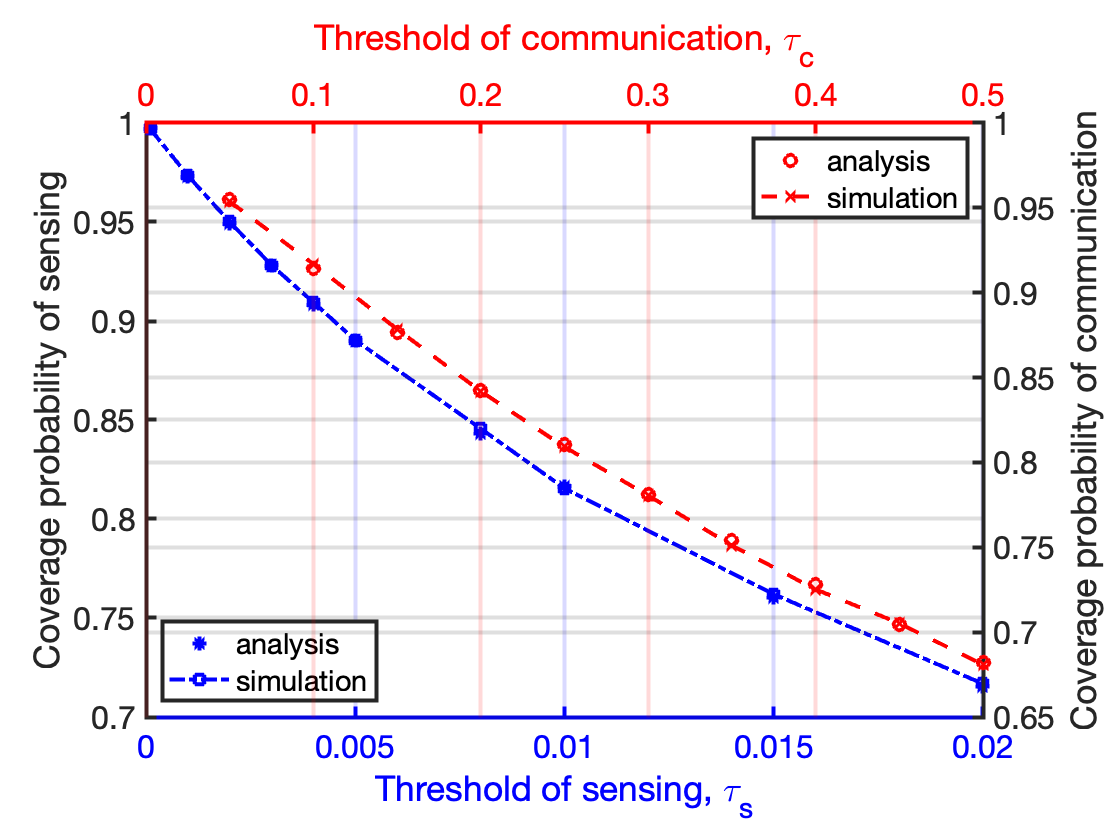

clc;close all;clear all;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

d_prime_s_res=0.2;  %% maximum distance resolution, m

tau_s_0=[0.0001,0.001,0.002,0.003,0.004,0.005,0.008,0.01,0.015,0.02];  %%  threshold in sensing

tau_c_0=[0.05,  0.1,  0.15, 0.2,  0.25, 0.3,  0.35, 0.4, 0.45, 0.5];  %% threshold/required data rate in communication

gamma_bs= 50/1000^2;  %%  density of base station, point/m^2

gamma_sct= 300/1000^2; %% density of SCT, point/m^2

gamma_st= 300/1000^2;   %% density of ST, point/m^2

eta=0.5;  %% first \beta part of the spectrum is allocated to sensing

mu=0.5;  %%  first \mu part of the power is allocated to sensing

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load('data/Ana_P_s_cov.mat');
load('data/Sim_P_s_cov.mat');

load('data/Ana_P_c_cov.mat');
load('data/Sim_P_c_cov.mat');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% figure();
% 
% plot(tau_s_0, Ana_P_s_cov,'--*r','LineWidth',2);hold on;
% plot(tau_s_0, Sim_P_s_cov,'--b','LineWidth',2);hold on;
% 
% legend('Analysis','Simulation');
% xlabel('Threshold for sensing, \tau_s');
% ylabel('Coverage probability of sensing' );
% 
% plot(tau_c_0, Ana_P_c_cov,'--*r','LineWidth',2);hold on;
% plot(tau_c_0, Sim_P_c_cov,'--b','LineWidth',2);hold on;
% 
% legend('Analysis','Simulation');
% xlabel('Threshold for communication, \tau_c');
% ylabel('Coverage probability of communictaion' );
% 
% ylim([0,1]);
% 
% set(gca,'LineWidth',2,'FontSize',16);
% grid on;





figure()

t = tiledlayout(1,1);
ax1 = axes(t);
plot(ax1,tau_s_0,Ana_P_s_cov,'b*','LineWidth',2);hold on
plot(ax1,tau_s_0,Sim_P_s_cov,'-.bs','LineWidth',2);hold on
ax1.XAxisLocation = 'bottom';
ax1.YAxisLocation = 'left';
ax1.Color = 'none';
ylabel('Coverage probability of sensing');
xlabel('Threshold of sensing, \tau_s');

set(gca,'xcolor','b');grid on;
lgd2=legend('analysis','simulation','Location','southwest');
set(gca,'LineWidth',2,'FontSize',16);

%%%%%%%%%%%%%%%%%%%%
ax2 = axes(t);
plot(ax2,tau_c_0,Ana_P_c_cov,'ro','LineWidth',2);hold on
plot(ax2,tau_c_0,Sim_P_c_cov,'--rx','LineWidth',2);
ax2.XAxisLocation = 'top';
ax2.YAxisLocation = 'right';
ax2.Color = 'none';
ylabel('Coverage probability of communication');
xlabel('Threshold of communication, \tau_c');
ax1.Box = 'off';
ax2.Box = 'off';
set(gca,'xcolor','r')
set(gca,'LineWidth',2,'FontSize',16);
lgd2=legend('analysis','simulation','Location','northeast');
grid on; hold off;



















%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


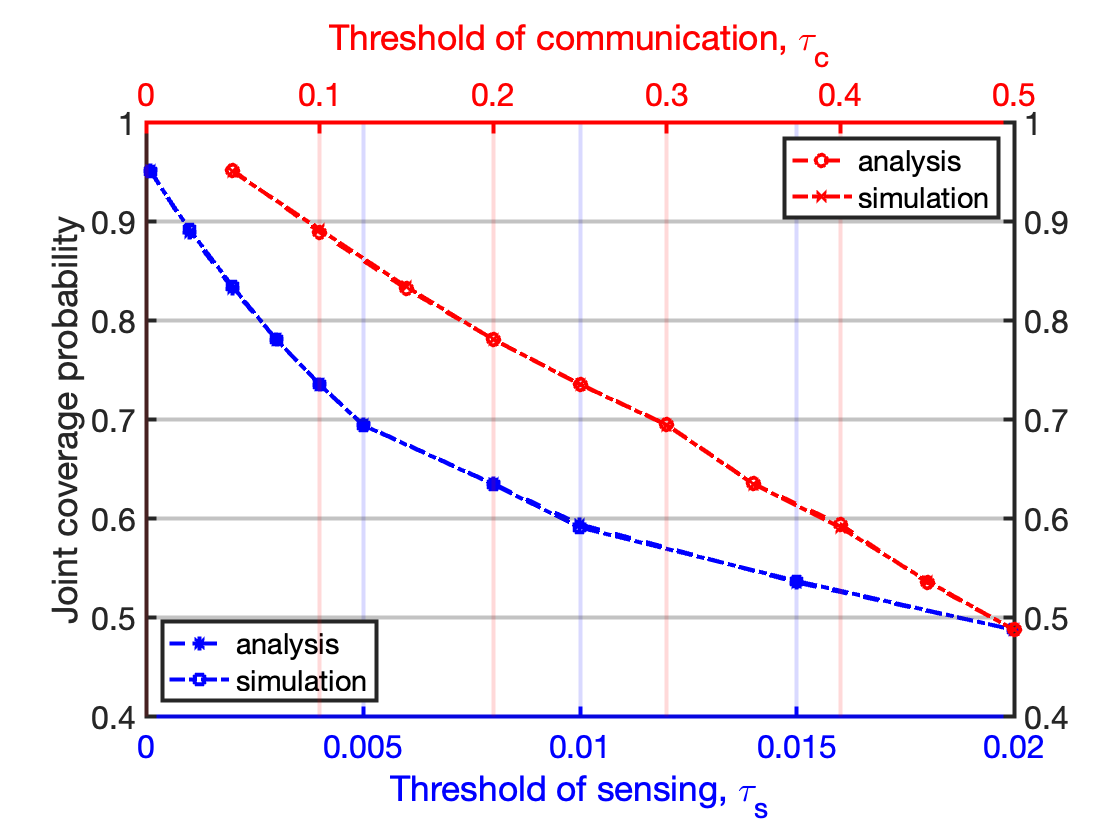

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


joint_Ana_P_cov=Ana_P_s_cov.*Ana_P_c_cov;
joint_Sim_P_cov=Sim_P_s_cov.*Sim_P_c_cov;

figure()

t = tiledlayout(1,1);
ax1 = axes(t);
plot(ax1,tau_s_0,joint_Ana_P_cov,'--b*','LineWidth',2);hold on
plot(ax1,tau_s_0,joint_Sim_P_cov,'-.bs','LineWidth',2);hold on
ax1.XAxisLocation = 'bottom';
ax1.YAxisLocation = 'left';
ax1.Color = 'none';
ylabel('Joint coverage probability');
xlabel('Threshold of sensing, \tau_s');

set(gca,'xcolor','b');grid on;
legend('analysis','simulation','Location','southwest')
set(gca,'LineWidth',2,'FontSize',16);

%%%%%%%%%%%%%%%%%%%%
ax2 = axes(t);
plot(ax2,tau_c_0,joint_Ana_P_cov,'--ro','LineWidth',2);hold on
plot(ax2,tau_c_0,joint_Sim_P_cov,'-.rx','LineWidth',2);
ax2.XAxisLocation = 'top';
ax2.YAxisLocation = 'right';
ax2.Color = 'none';
xlabel('Threshold of communication, \tau_c')
ax1.Box = 'off';
ax2.Box = 'off';
set(gca,'xcolor','r')
set(gca,'LineWidth',2,'FontSize',16);
legend('analysis','simulation','Location','northeast')
grid on; hold off;

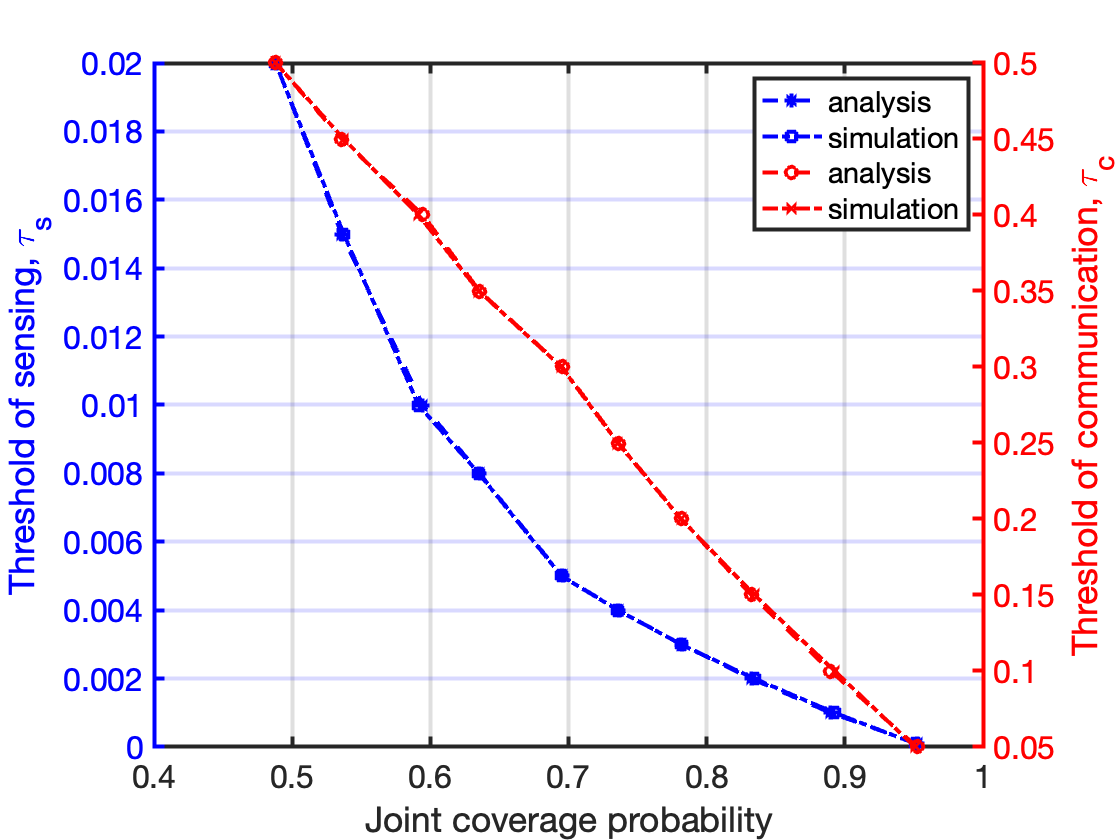


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure()

colororder({'b','r'})
yyaxis left
plot(joint_Ana_P_cov,tau_s_0,'--*','LineWidth',2);hold on;
plot(joint_Sim_P_cov,tau_s_0,'-.s','LineWidth',2);hold on;
ylabel('Threshold of sensing, \tau_s');
grid on;

yyaxis right
plot(joint_Ana_P_cov,tau_c_0,'--o','LineWidth',2);
plot(joint_Sim_P_cov,tau_c_0,'-.x','LineWidth',2);
xlabel('Joint coverage probability' );
grid on; 

ylabel('Threshold of communication, \tau_c')
legend('analysis','simulation','analysis','simulation','Location','northeast')
set(gca,'LineWidth',2,'FontSize',16);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


joint_Ana_P_cov=Ana_P_s_cov.*Ana_P_c_cov;
joint_Sim_P_cov=Sim_P_s_cov.*Sim_P_c_cov;

figure()

t = tiledlayout(1,1);
ax1 = axes(t);

plot(ax1,Ana_P_s_cov,'bo','LineWidth',1.5);hold on
plot(ax1,Sim_P_s_cov,'b--','LineWidth',2);hold on

plot(ax1,joint_Ana_P_cov,'m*','LineWidth',2);hold on
plot(ax1,joint_Sim_P_cov,'m-','LineWidth',2);hold on

ax1.XAxisLocation = 'bottom';
ax1.YAxisLocation = 'left';
ax1.Color = 'none';
ax1.YLabel.String='Coverage probability';
ax1.XLabel.String='Threshold of sensing, \tau_s';
set(gca,'xcolor','b');
% grid on;
set(gcf,'color','none');
% set(gca,'color','none');

lgd1=legend('Sensing, Analysis','Sensing, Simulation','Joint, Analysis','Joint, Simulation','Location','southwest')

lgd1 =   Legend (Sensing, Analysis, Sensing, Simulation, Joint, Analysis, Joint, Simulation) - 属性:

         String: {'Sensing, Analysis'  'Sensing, Simulation'  'Joint, Analysis'  'Joint, Simulation'}
       Location: 'southwest'
    Orientation: 'vertical'
       FontSize: 9.900000000000000
       Position: [0.144285714285714 0.130238095238095 0.230357142857143 0.127380952380952]
          Units: 'normalized'

  显示 所有属性


lgd1.Color = 'white';
set(gca,'LineWidth',2,'FontSize',16);


ax2 = axes(t);

plot(ax2,Ana_P_c_cov,'rs','LineWidth',1.5);hold on
plot(ax2,Sim_P_c_cov,'r-.','LineWidth',2);hold on

plot(ax2,joint_Ana_P_cov,'m*','LineWidth',1.5);hold on
plot(ax2,joint_Sim_P_cov,'m-','LineWidth',2);hold on



ax2.XAxisLocation = 'top';
ax2.YAxisLocation = 'right';
ax2.Color = 'none';
xlabel('Threshold of communication, \tau_c')
% ylim([0.6,1])
ax1.Box = 'off';
ax2.Box = 'off';
set(gca,'xcolor','r')
set(gcf,'color','none');
set(gca,'LineWidth',2,'FontSize',16);
lgd2=legend('Comm., Analysis, ','Comm., Simulation','Location','northeast')

lgd2 =   Legend (Comm., Analysis,, Comm., Simulation) - 属性:

         String: {'Comm., Analysis,'  'Comm., Simulation'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 14.400000000000000
       Position: [0.597857142857143 0.740000000000000 0.292857142857143 0.094047619047619]
          Units: 'normalized'

  显示 所有属性


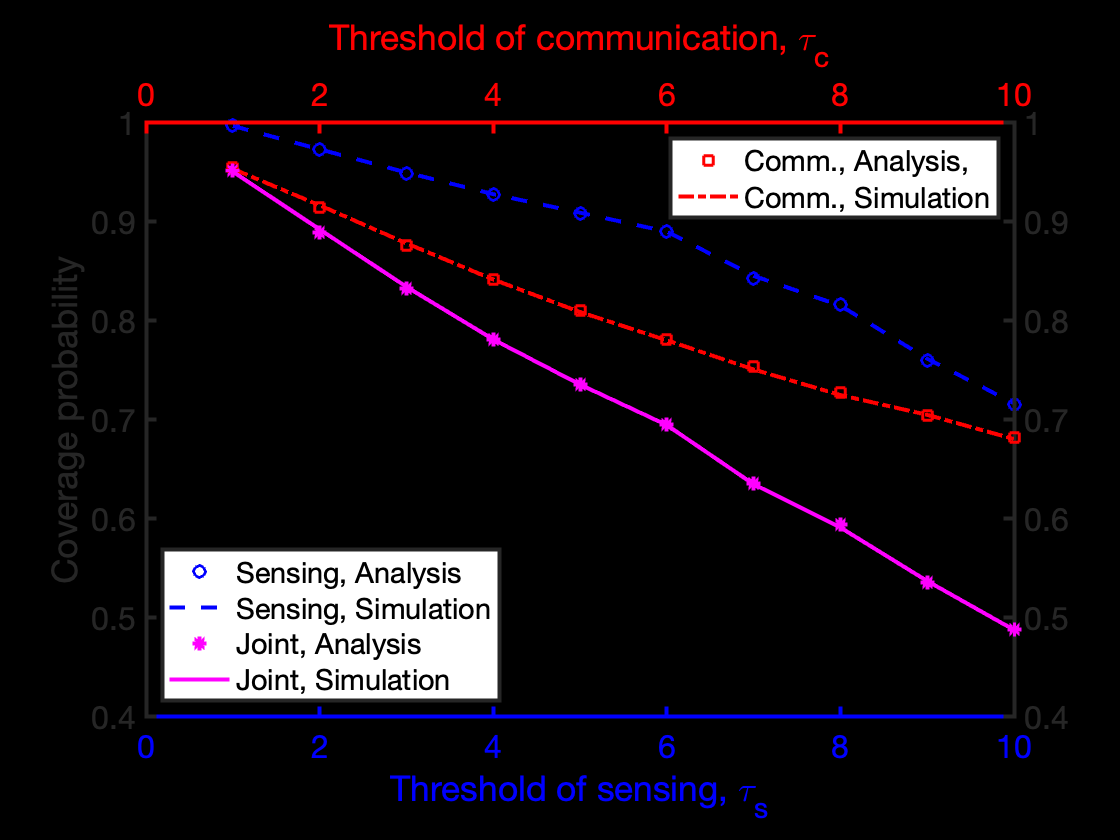

lgd2.Color = 'white';
hold off;